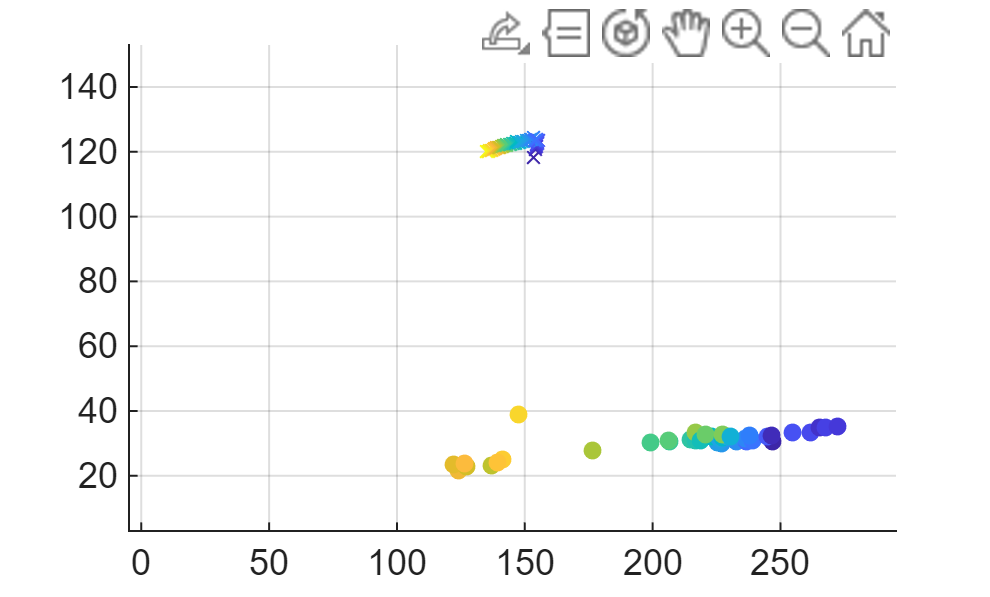

%compare unadjusted and background
figure;
hold on;
colors = summer(numel(raw_data.pixel_color));
for i = 1:numel(raw_data.pixel_color)
    databuf = raw_data.pixel_color{i};
    if (~isempty(databuf))
        frameMean = [mean(databuf(:, 1)), mean(databuf(:, 2)), mean(databuf(:, 3))];
    else
        frameMean = [0 0 0];
    end
    scatter3(frameMean(1), frameMean(2), frameMean(3), 20, colors(i), 'filled', 'o');
    scatter3(amplify(i,1), amplify(i, 2), amplify(i, 3), 20, colors(i), 'x');
    x = [frameMean(1), amplify(i,1)];
    y = [frameMean(2), amplify(i,2)];
    z = [frameMean(3), amplify(i,3)];
    %plot3(x, y, z, 'Color', 'black');
end

grid on;
hold off;

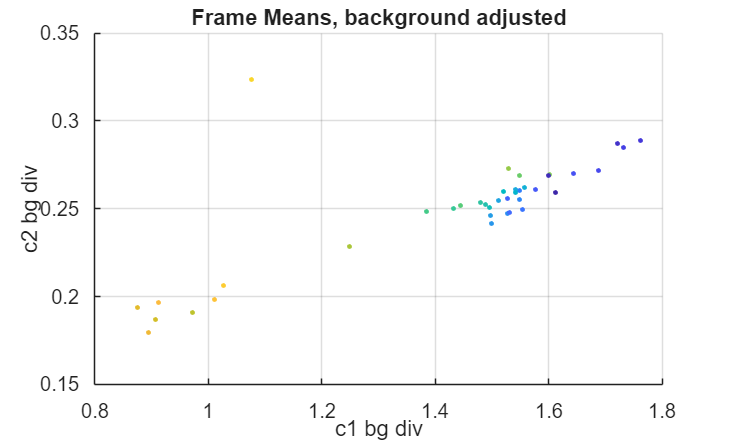

%compare frame mean
figure;
hold on;
colors = cool(numel(adjflo));
for i = 1:numel(adjflo)
    data = adjflo{i};
    c1 = mean(data(:, 1), 'all');
    c2 = mean(data(:, 2), 'all');
    c3 = mean(data(:, 3), 'all');
    scatter3(c1, c2, c3, 6, colors(i),'filled');
end
xlabel('c1 bg div');
ylabel('c2 bg div');
zlabel('c3 bg div');
title('Frame Means, background adjusted');
grid on;
hold off;

%frame mean vs frame number
figure;
hold on;
colors = summer(3)

colors =          0    0.5000    0.4000
    0.5000    0.7500    0.4000
    1.0000    1.0000    0.4000


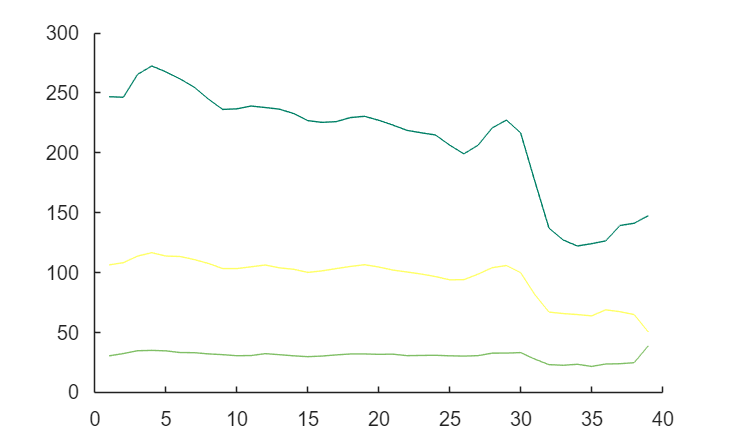

x = linspace(1, 39, 39);
plot(x, axon_frame_raw1057.c1, 'Color',colors(1, :));
plot(x, axon_frame_raw1057.c2, 'Color',colors(2, :));
plot(x, axon_frame_raw1057.c3, 'Color',colors(3, :));
hold off;

%coeffients
bg_fmeans_adj = zeros([numel(adjflo), 3]);

for i = 1:numel(adjflo)
    data = adjflo{i};
    if (~isempty(data))
        c1 = mean(data(:, 1), 'all');
        c2 = mean(data(:, 2), 'all');
        c3 = mean(data(:, 3), 'all');
        bg_fmeans_adj(i, :) = [c1, c2, c3];
    end

end
bg_fmeans_adj(bg_fmeans_adj==0)= NaN;
bg_ftotal_stds = std(bg_fmeans_adj, 0, 1, 'omitnan');
bg_ftotal_means = mean(bg_fmeans_adj, 1, 'omitnan');
coe_adj = bg_ftotal_stds./bg_ftotal_means;

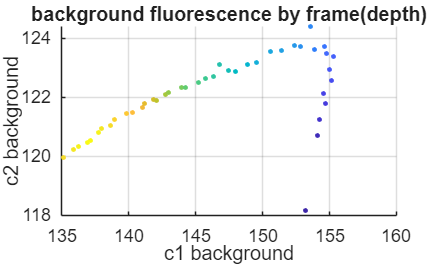

%plotting background color
figure;
hold on;
for i = 1:43
    scatter3(indx(i, 1), indx(i, 2), indx(i, 3), ...
        6, colors(i), "filled");
end

xlabel('c1 background');
ylabel('c2 background');
zlabel('c3 background');
title('background fluorescence by frame(depth)');
grid on;
hold off;

bg_ftotalraw_means = [mean(axon_frame_raw1057.c1), ...
    mean(axon_frame_raw1057.c2), mean(axon_frame_raw1057.c3)];
bg_ftotalraw_stds = [std(axon_frame_raw1057.c1), ...
    std(axon_frame_raw1057.c2), std(axon_frame_raw1057.c3)];
coe_raw = bg_ftotalraw_stds./bg_ftotalraw_means;

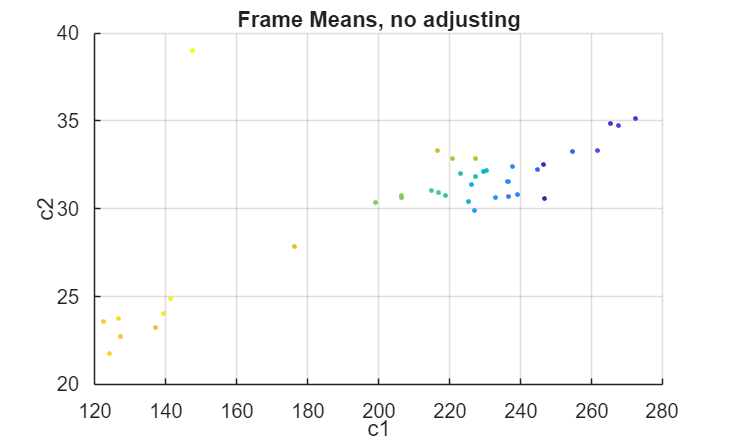

figure;
hold on;

colors = cool(height(axon_frame_raw1057));
for j = 1:height(axon_frame_raw1057)
    scatter3(axon_frame_raw1057.c1(j), ...
        axon_frame_raw1057.c2(j), axon_frame_raw1057.c3(j), 6, colors(j), "filled");
end
xlabel('c1');
ylabel('c2');
zlabel('c3');
title('Frame Means, no adjusting');
grid on;
hold off;

%pixel level
adj_pixels = [];
for i = 1:numel(adjflo)
    data = adjflo{i};
    if (~isempty(data))
        adj_pixels = [adj_pixels; data]; % Accumulate adjusted pixel data
    end
end
% Further analysis or processing can be done here
means_adj = [mean(adj_pixels(:, 1)), mean(adj_pixels(:, 2)), mean(adj_pixels(:, 3))];
std_adj = [std(adj_pixels(:, 1)), std(adj_pixels(:, 2)), std(adj_pixels(:, 3))];
coe_pixel_adj = std_adj./means_adj;

means_raw = [mean(axonpixel_1057.c1), mean(axonpixel_1057.c2), mean(axonpixel_1057.c3)];
std_raw = [std(axonpixel_1057.c1), std(axonpixel_1057.c2), std(axonpixel_1057.c3)];
coe_pixel_raw = std_raw./means_raw;

%read csv files in this folder and output to table
folder_path = "H:\Data_connectome\trace_pipe_DJ\4111\exported_color\brain";
csv_files = dir(fullfile(folder_path, '*.csv'));
num_files = length(csv_files);
avg_c1 = zeros(num_files, 1);
avg_c2 = zeros(num_files, 1);
avg_c3 = zeros(num_files, 1);
std_c1 = zeros(num_files, 1);
std_c2 = zeros(num_files, 1);
std_c3 = zeros(num_files, 1);
file_names = cell(num_files, 1);
for i = 1:num_files
    file_path = fullfile(folder_path, csv_files(i).name);

    % Read the CSV file
    data = readtable(file_path);
    data_sum = data.c1 + data.c2 + data.c3;
    % Calculate percentiles
    p60 = prctile(data_sum, 60);  % 60th percentile (bottom 60%)
    p99 = prctile(data_sum, 99);  % 99th percentile (top 1%)
    filter_idx = (data_sum > p60) & (data_sum < p99);

    % Apply filter to data
    filtered_c1 = data.c1(filter_idx);
    filtered_c2 = data.c2(filter_idx);
    filtered_c3 = data.c3(filter_idx);

    % Extract columns and compute averages and standard deviations
    avg_c1(i) = mean(filtered_c1);
    avg_c2(i) = mean(filtered_c2);
    avg_c3(i) = mean(filtered_c3);
    std_c1(i) = std(filtered_c1);
    std_c2(i) = std(filtered_c2);
    std_c3(i) = std(filtered_c3);
    % Extract numeric value from file name
    [~, name, ~] = fileparts(csv_files(i).name);
    
    % Extract all numbers from the filename
    numbers = regexp(name, '\d+', 'match');
    if ~isempty(numbers)
        file_names{i} = numbers{1};  % Use the first number found
    else
        file_names{i} = name;  % Fallback to full name if no number found
    end
    
    fprintf('Processed: %s\n', csv_files(i).name);
end

Processed: 1057_axon_color_pixeldata.csv
Processed: 1058_axon_color_pixeldata.csv
Processed: 1059_axon_color_pixeldata.csv
Processed: 1060_axon_color_pixeldata.csv
Processed: 1061_axon_color_pixeldata.csv
Processed: 1062_axon_color_pixeldata.csv
Processed: 1063_axon_color_pixeldata.csv
Processed: 1064_axon_color_pixeldata.csv
Processed: 1065_axon_color_pixeldata.csv
Processed: 1066_axon_color_pixeldata.csv


% Create 3D scatter plot
figure('Position', [100, 100, 900, 700]);
hold on;
colors = parula(num_files)

colors =     0.2422    0.1504    0.6603
    0.2803    0.2782    0.9221
    0.2440    0.4358    0.9988
    0.1540    0.5902    0.9218
    0.0297    0.7082    0.8163
    0.1938    0.7758    0.6251
    0.5044    0.7993    0.3480
    0.8634    0.7406    0.1596
    0.9892    0.8136    0.1885
    0.9769    0.9839    0.0805


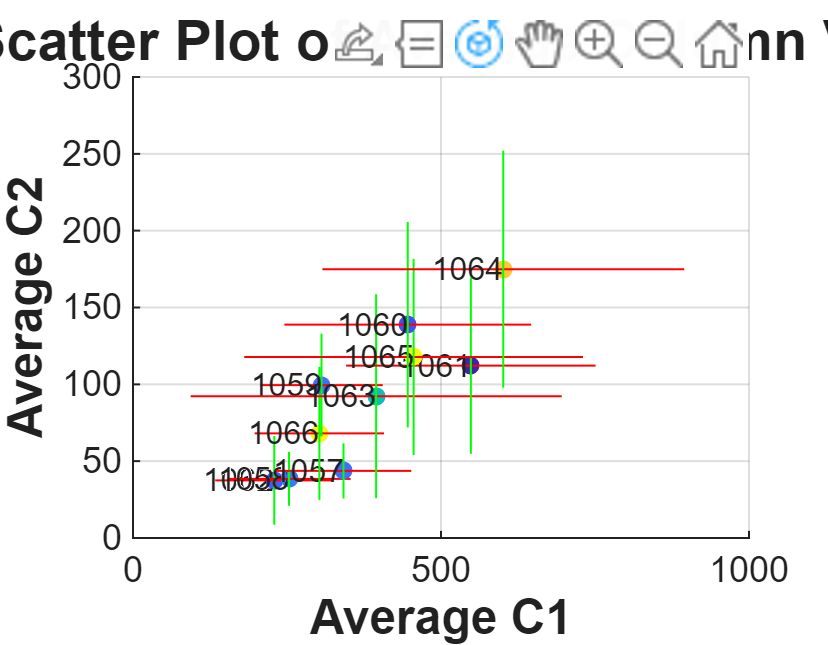

for i = 1:num_files
    scatter3(avg_c1(i), avg_c2(i), avg_c3(i), 20, colors(i),"filled");
    plot3([avg_c1(i)-std_c1(i), avg_c1(i)+std_c1(i)], [avg_c2(i), avg_c2(i)], ...
        [avg_c3(i), avg_c3(i)], 'r-', 'LineWidth', 0.5);

    % Error bar along C2 direction
    plot3([avg_c1(i), avg_c1(i)], [avg_c2(i)-std_c2(i), avg_c2(i)+std_c2(i)], ...
        [avg_c3(i), avg_c3(i)], 'g-', 'LineWidth', 0.5);

    % Error bar along C3 direction
    plot3([avg_c1(i), avg_c1(i)], [avg_c2(i), avg_c2(i)], [avg_c3(i)-std_c3(i), ...
        avg_c3(i)+std_c3(i)], 'b-', 'LineWidth', 0.5);
end

% Add labels and title
xlabel('Average C1', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Average C2', 'FontSize', 12, 'FontWeight', 'bold');
zlabel('Average C3', 'FontSize', 12, 'FontWeight', 'bold');
title('3D Scatter Plot of Average Column Values', 'FontSize', 14, 'FontWeight', 'bold');

% Add grid and adjust appearance
grid on;
rotate3d on;
for i = 1:num_files
    text(avg_c1(i), avg_c2(i), avg_c3(i), file_names{i}, 'FontSize', 8, 'HorizontalAlignment', 'right');
end
hold off;